close all;
clear all;
clc;

fontsize=15;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_2D_turn_chemical_reaction');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_2D_turn_chemical_reaction


### Plotting the results of the chemical reaction in 0D 

**Description**: This section plots the exported results for the chemical reaction in COMSOL.

%reading the chemical reaction dataset from COMSOL
% Specify the MAT file for the chemical reaction
csvFileName = 'chemical_reaction.csv';
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview
chem_reaction_table=readtable(csvFileName,opts);
%mapping the concentration variables for reactants and products with the
%table columns
time=chem_reaction_table.Var1;
c_CH3COOH=chem_reaction_table.Var2;
c_NaOH=chem_reaction_table.Var3;
c_CH3COONa=chem_reaction_table.Var4;
c_H2O=chem_reaction_table.Var5;


figure;
%Plotting the reactants
plot(time*10^6,c_CH3COOH,'LineWidth',2); grid on; hold on
plot(time*10^6,c_NaOH,'s--','MarkerIndices',15:30:length(c_NaOH),'LineWidth',2);
%Plotting the products
plot(time*10^6,c_CH3COONa,'LineWidth',2); grid on; hold on
plot(time*10^6,c_H2O,'o--','MarkerIndices',15:30:length(c_NaOH),'LineWidth',2);

xlabel('Time [$\mu$s]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
legend('CH3COOH','NaOH','CH3COONa','H2O');
set(gca,'FontSize',fontsize);
axis([0 time(end/2)*10^6 0 1.1*max(c_CH3COOH)]);


### Plotting the velocity within the pipe

%reading the velocity surface in COMSOL
% Specify the MAT file for the chemical reaction
csvFileName = 'velocity.csv';
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview

ans = 8×3 table
       Var1          Var2          Var3  
    __________    ___________    ________

         3e-05      1.397e-06    0.046938
     2.899e-05     1.0035e-06    0.032677
         3e-05    -4.2352e-22           0
     2.846e-05              0           0
    2.8862e-05     2.1833e-06    0.060404
         3e-05     2.8308e-06    0.073645
     2.764e-05     1.2495e-06    0.038029
    2.6879e-05              0           0


velocity_table=readmatrix(csvFileName,opts);
%mapping the concentration variables for reactants and products with the
%table columns

x = velocity_table(:,1);    % x-coordinate  
y = velocity_table(:,2);    % y-coordinate  
V = velocity_table(:,3);    % velocity magnitude  

% Determine grid size (assumes x repeats every Ny points)
x_unique = unique(x);
y_unique = unique(y);

[Xq,Yq] = meshgrid( x_unique, y_unique );  % Ny×Nx grid of query points
Zq = griddata(x, y, V, Xq, Yq, 'linear');  % interpolate V onto that grid

%deleting the remainder of interporlation
Zq(isnan(Zq)) = 0;
%we use rectangles to delete the remainders of interpolation
x_rect=190

x_rect = 190

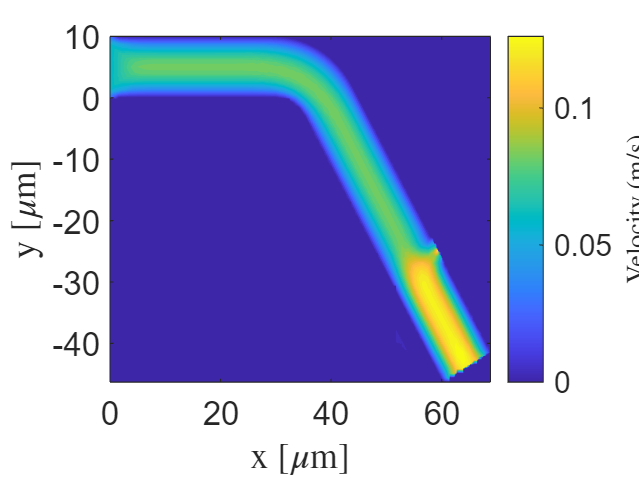

y_rect=320;
Zq(1:y_rect,1:x_rect)=zeros(y_rect,x_rect);
%Rectangle 2
x_init_rect=x_rect;
x_rect=305;
y_init_rect=1;
y_rect=200;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 3
x_init_rect=x_rect;
x_rect=360;
y_init_rect=1;
y_rect=140;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 4
x_init_rect=x_rect;
x_rect=400;
y_init_rect=1;
y_rect=100;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);


figure;
contourf(Xq*10^6,Yq*10^6,Zq,40, 'LineColor','none');
% contourf(Xq,Yq,Zq,40, 'LineColor','none');
shading interp;
% add and label the colorbar
cb = colorbar;                        % add colorbar
cb.Label.String    = 'Velocity (m/s)';% set its label
cb.Label.FontSize  = 12;              % tweak font size
cb.Label.Interpreter = 'latex';       % if you want LaTeX formatting
xlabel('x [$\mu$m]','Interpreter','latex');
ylabel('y [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting the velocity within the pipe

%reading the velocity surface in COMSOL
% Specify the MAT file for the chemical reaction
csvFileName = 'CH3COOH.csv';
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview

ans = 8×3 table
       Var1          Var2         Var3  
    __________    ___________    _______

         3e-05      1.397e-06      1.236
     2.899e-05     1.0035e-06     1.5243
         3e-05    -4.2352e-22      1.653
     2.846e-05              0     1.6887
    2.8862e-05     2.1833e-06    0.73262
         3e-05     2.8308e-06    0.39778
     2.764e-05     1.2495e-06     1.4112
    2.6879e-05              0     1.7023


velocity_table=readmatrix(csvFileName,opts);
%mapping the concentration variables for reactants and products with the
%table columns

x = velocity_table(:,1);    % x-coordinate  
y = velocity_table(:,2);    % y-coordinate  
V = velocity_table(:,3);    % velocity magnitude  

% Determine grid size (assumes x repeats every Ny points)
x_unique = unique(x);
y_unique = unique(y);

[Xq,Yq] = meshgrid( x_unique, y_unique );  % Ny×Nx grid of query points
Zq = griddata(x, y, V, Xq, Yq, 'linear');  % interpolate V onto that grid

%deleting the remainder of interporlation
Zq(isnan(Zq)) = 0;
%we use rectangles to delete the remainders of interpolation
x_rect=190

x_rect = 190

y_rect=320;
Zq(1:y_rect,1:x_rect)=zeros(y_rect,x_rect);
%Rectangle 2
x_init_rect=x_rect;
x_rect=305;
y_init_rect=1;
y_rect=200;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 3
x_init_rect=x_rect;
x_rect=360;
y_init_rect=1;
y_rect=140;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 4
x_init_rect=x_rect;
x_rect=400;
y_init_rect=1;
y_rect=100;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);


figure;
contourf(Xq*10^6,Yq*10^6,Zq,40, 'LineColor','none');
% contourf(Xq,Yq,Zq,40, 'LineColor','none');
shading interp;
% add and label the colorbar
cb = colorbar;                        % add colorbar
cb.Label.String    = 'Velocity (m/s)';% set its label
cb.Label.FontSize  = 12;              % tweak font size
cb.Label.Interpreter = 'latex';       % if you want LaTeX formatting
xlabel('x [$\mu$m]','Interpreter','latex');
ylabel('y [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Evaluating the Reynold number

Description: The Reynold ($\mathrm{Re}$) number defines the ratio inertial/viscous forces. In a microfluidic environment where the fluid is expeted to be laminar the viscous forces should dominate. Thereby we expect $\mathrm{Re}<1$.

%This evaluation follows [1, Eq. (3.36) pp. 52]
Re=rho_Water/mu_Water*v0_char*2*radius_cylinder_1

### Evaluating the Péclet number

**Description**: The Péclet ($Pe$) number defines the ratio (diffusion time)/(convection time). This ratio defines wheter diffusion or convection dominates. If the convection time is less than diffussion, then the particles haven't diffused within the convection time interval, in this case $Pe<1$. Whenever the convection time is larger than diffusion, it means that the particles has diffused before the convection time, i.e., $Pe>1$. The Péclet number is analyzed taking the diffusion time as the one needed for the particles to travel along the radius of the microfluid, i.e., given by $\tau_\mathrm{diff}^r=\frac{r^2}{D}$, where $r$ is the radius of the microfluidic pipe and $D$ is the diffusion coefficient of the particle. Similarly, is for the convection time, given by $\tau_\mathrm{conv}^r=\frac{r}{V_0}$, where $V_0$ is the average fluid velocity within the Pouseille flow.

%This evaluation follows [1,Eq. (4.44) pp.75]
Pe=radius_cylinder_1*v0_char/D_Na


The particles are observed (at any point in x-axis) to diffuse homogenously whenever the condition $Pe\ll \frac{4L}{r}$ is met, where $L$ is the length of the microfluidic channel; see [1, Eq. (4.52) pp. 77]. Besides, diffusion effectively ocurred at any observation point $x$ whenever the dispersion coefficient satisfies $D_\mathrm{eff}\gg D$, where $D_\mathrm{eff}=\frac{r^2V_0^2}{48D}$ or $Pe\ll \sqrt{48}$; see [1, Eq.(4.54) pp.77].  Both conditions entails the relation:

$\sqrt{48}\ll Pe \ll 4\frac{L}{r}$.       (1)

if(Pe<4*width_cylinder_out_1/radius_cylinder_1)
    disp(['Concentration is constant along the x-axis'])
else
    disp(['Concentration is not constant along the x-axis'])
end

if(Pe>sqrt(48))
    disp(['Diffusion occurred along the radial axis'])
else
    disp(['Diffusion hasn''t occurred along the axis'])
end

### Evaluating the Effective Diffusion

D_eff=radius_cylinder_1^2*v0^2/48/D_Na


### Evaluating the concentration level

**Description**: This section evaluates the concentration level observed at the ouptup of the rectangular pipes (straigth and turning). The evaluation is performed theoretical and following the simulations provided by COMSOL. Following COMSOL we have the following files

- `concentration_outlet_turn_rectangle.csv`: This file stores the average concentration for the inclined outlet line. This line develops a similar condition to the outlet of the turning channel.

- `concentration_outlet_turn.csv`: This file stores the average concentration for the outlet of the turning channel.

Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition in the above Eq. (1), the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$ as [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$.

where the solution is [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (2)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x-v_0t}{2\sqrt{D_\mathrm{eff}\,t}}$,          (3)

where [1, Eq. (4.54) pp. 77]

$D_\mathrm{eff}=\frac{a^2v_0^2}{48D}$,                                   (4)

is the effective diffusion coefficient, and $v_0$ is the characteristic speed, here given as the average speed within the microfluidic pipe.

Besides, as the turning channel introduces the reacetrack effect, a turn is also similar to additionally shift the coordinate $x$ in Eq. (3) on a straight pipe. As the concentration solution en Eq. (3) is valid regardless $y$, after the turn each lamina well be delayed in the amount $l-l_\mathrm{in}=\phi r_l - \phi r_\mathrm{in}=\phi \Delta r_l$, where $l$ refers to the length of the arcus on a given lamina, $\phi$ is the angle of the turn and $r_l$ is the radius of the arc. As such, Eq.(3) after a turn becomes


$$C(x,t)=\int_{r_\Delta=0}^{r_\Delta=r_\mathrm{out}-r_\mathrm{in}}\frac{1}{2}C_0\, \mathrm{erfc}\left(\frac{x-v_0t-\phi r_\Delta}{2\sqrt{D_\mathrm{eff}\,t}}\right)dr_\Delta$$


which is evaluated after using the primitive of this integral as


$$\int{\mathrm{erfc}(x)dx}=x\cdot\mathrm{erfc}(x)-\frac{e^{-x^2}}{\sqrt{\pi}}$$


yields


$$C(x,t)=2\,\mathrm{dr}+\mathrm{dr}\,\left(\mathrm{erf}\left(\frac{\mathrm{angle}\,\mathrm{dr}-x+t\,v_{0}}{2\,\sqrt{D\,t}}\right)-1\right)-\frac{\left(x-t\,v_{0}\right)\,\left(\mathrm{erf}\left(\frac{\mathrm{angle}\,\mathrm{dr}-x+t\,v_{0}}{2\,\sqrt{D\,t}}\right)-1\right)}{\mathrm{angle}}-\frac{\left(x-t\,v_{0}\right)\,\left(\mathrm{erf}\left(\frac{x-t\,v_{0}}{2\,\sqrt{D\,t}}\right)+1\right)}{\mathrm{angle}}-\frac{2\,{\mathrm{e}}^{-\frac{{\left(x-t\,v_{0}\right)}^2}{4\,D\,t}}\,\sqrt{D\,t}}{\mathrm{angle}\,\sqrt{\pi }}+\frac{2\,{\mathrm{e}}^{-\frac{{\left(\mathrm{angle}\,\mathrm{dr}-x+t\,v_{0}\right)}^2}{4\,D\,t}}\,\sqrt{D\,t}}{\mathrm{angle}\,\sqrt{\pi }}$$



%Matlab code to evaluate the integral
syms z x Delta_r rd real

% Define the substitution for x
z = (x - v0*t - angle*rd) / (2*sqrt(D_eff*t));

% Define the integrand
integrand = erfc(z);

% Perform the symbolic integration from r = 0 to r = dr
I = simplify(int(integrand, rd, 0, Delta_r));

% % Display the result
% disp('The integral of erfc(x) from r = 0 to r = dr is:')
% disp(latex(I))




% Specify the MAT file for the concentration at the outlet
csvFileName = 'concentration_outlet_turn_rectangle.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_conc_outlet_turn_rectangle=readtable(csvFileName,opts);

% Specify the MAT file for the concentration at the outlet
csvFileName = 'concentration_outlet_turn.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_conc_outlet_turn=readtable(csvFileName,opts);




%reading the concentration value from COMSOL
% Specify the MAT file for the concentration at the outlet
csvFileName = 'concentration_outlet.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_conc_outlet=readtable(csvFileName,opts);

t=table_conc_outlet.Var1;
c=10*1./2.*erfc((L-v0*t)./(2*sqrt(D_eff*t)));
figure;
plot(t*10^3,c,'LineWidth',2); grid on; hold on;
plot(table_conc_outlet.Var1*10^3,table_conc_outlet.Var2,'o-','MarkerIndices',1:30:length(table_conc_outlet.Var2),'LineWidth',2);
plot(table_conc_outlet_turn.Var1*10^3,table_conc_outlet_turn.Var2,'s--','MarkerIndices',15:30:length(table_conc_outlet_turn.Var2),'LineWidth',2);
xlabel('Time [ms]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend('Theoretical formulation','COMSOL simulation in straight channel','COMSOL simulation in turning channel');
axis([0 time_simul*10^3 0 c_Na*1.1])
L/v0_char*10^3
L^2/D_Na



syms t
c=1./sqrt(4*pi*D_Na*t)^3.*exp(-(L-v0_char*t).^(2)./(4*D_Na*t));
figure;
fplot(c,[0.01 0.0109],'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %var=eval(str{1});
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','m^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end
    
end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] J. Crank. 1986. The Mathematics of Diffusion. Oxford University Press.